# Accompanying MATLAB Code for *Approaches for Implementing Phonograph Record Playback Equalization in the Z-Domain*

Presented at the 157th Convention of the Audio Engineeering Society (AES) in New York City, New York, 2024

Authors: Benjamin R Thompson, Tre DiPassio, and Jenna Rutowski

The sections labeled as "Interactive" are meant to walk the reader through the various methods for discritization that are defined in the paper

## 1) Introduction

As mentioned in Section 1 of the paper, almost all electrically recorded records are cut with some equalization curve that allows the cutter to switch between a constant-velocity response and a constant-amplitude response for different bands within the audible spectrum. For laterally-cut grooves, this allows for smaller groove widths and thus more information for a given area. Cutting with an equalization curve also creates a need to apply an inverse equalization curve when playing back the record. Since 1954, the RIAA curve has been the standard equalization curve used to cut records. The playback curve for records cut with the RIAA standard is depicted below, modified from Moyer (Paper Reference [1], <[https://www.aes.org/aeshc/pdf/moyer_evolution-of-a-recording-curve.pdf](https://www.aes.org/aeshc/pdf/moyer_evolution-of-a-recording-curve.pdf)>):

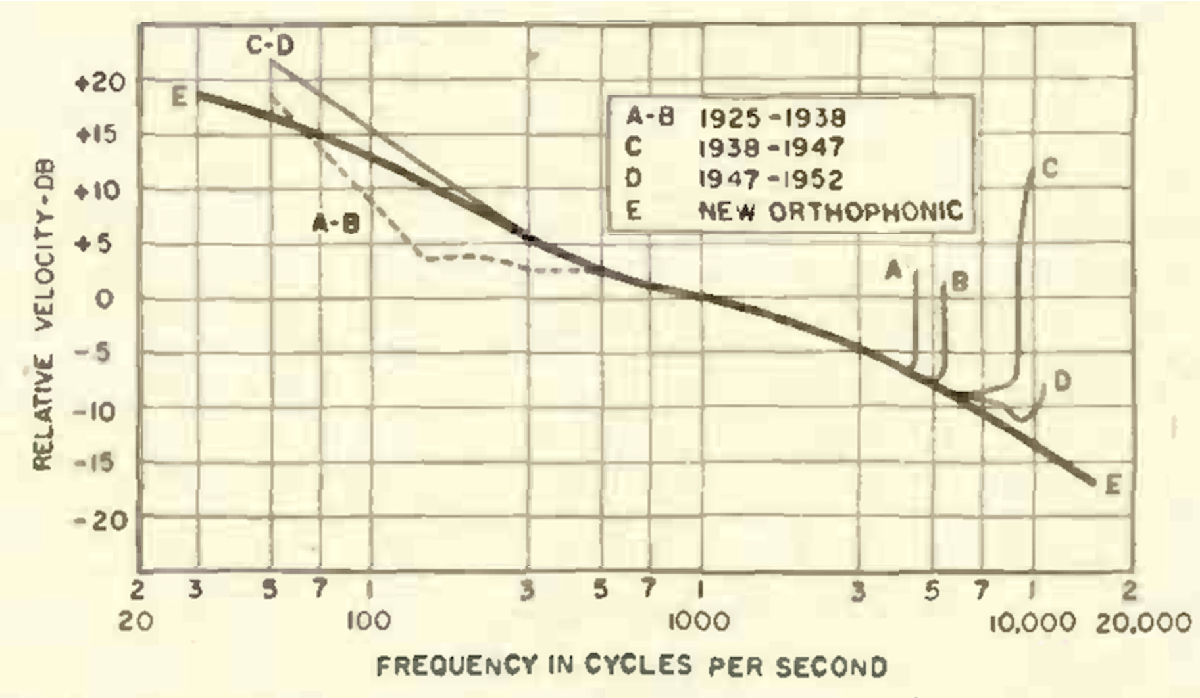

The RIAA standard curve is defined by three time constants that determine the curve's treble rolloff, bass boost, and bass shelving frequency. Many curves will be defined by three time constants, though older curves may require as few as a single time constant which would describe the turnover frequency for the bass boost. Most playback devices made after 1954 include analog circuity to apply the curve in the above figure to equalize the signal before playback. For example, if you analyzed or simulated the circuit below (Reproduced directly from *Small Signal Audio Design *by Douglas Self*)*, you would get a transfer function that looked identical to the RIAA playback curve depicted above:

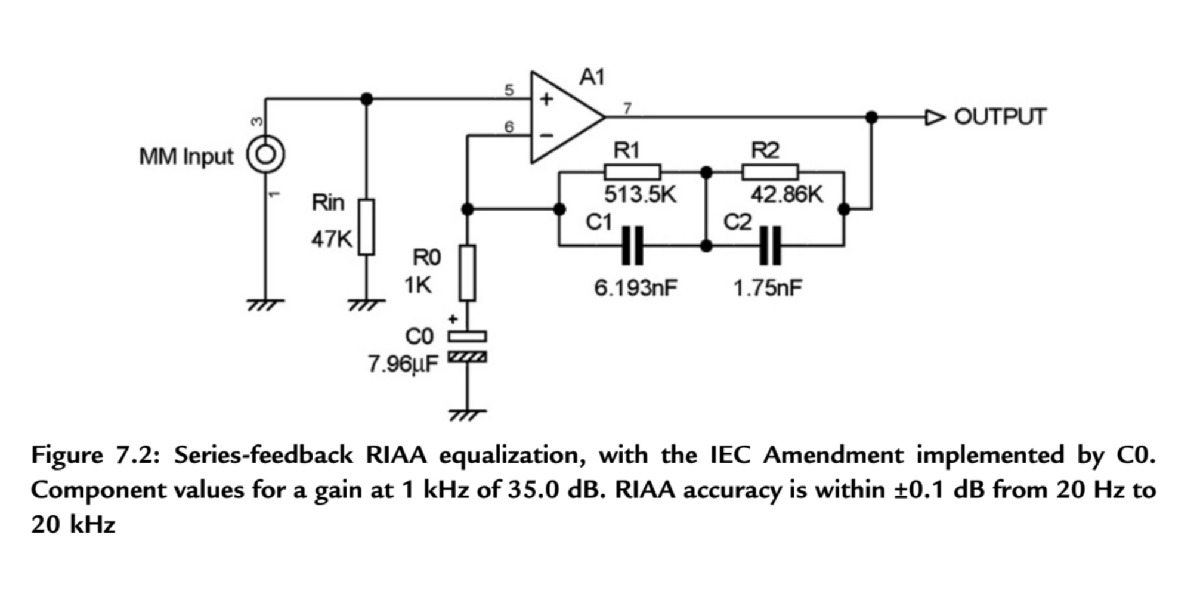

Before the adoption of the RIAA standard, the required playback curve for a disc could vary with record company and over time. Therefore, anyone seeking to hear or restore the information from older discs must have access to multiple playback curves. This is often accomplished by utilizing hardware with an onboard analog equalizer, but this approach has some drawbacks. Hardware, such as the INSERT shown below, can be 

A digital approach has the advantages of reduced cost and expanded versatility, but requires a transformation from the s-domain, where the original curves are defined, to the z-domain. This transformation inevitably comes with some compromise in magnitude and phase accuracy. In this work, several approaches to performing this transformation are explored in the context of playback equalization, and the compromises of each approach are quantified.

The circuits are granular

In this MATLAB script, we will compare many 

The desire to mirror the characteristics of continuous-time filters with filters implemented in discrete time is common in musical applications where we wish to replicate the characteristics of analog equipment using digital processing. In most cases, while it is desirable for the filter response to be as close as possible to the response of the analog version, in use, performance is subjective; a mix engineer deems it acceptable, adjusts the settings, or replaces it with a different processor. There is no objectively correct filter response; the only arbiter is the end-user. In this way, playback equalization presents a unique use case for digital filtering because the information on the media has effectively been encoded using continuous time filters and must be decoded using discrete time filters. In this application, there is an objectively correct response (though it may not always be known to the operator). This has the effect that the criteria for replicating the response of an analog playback filter may be even more rigorous than in other use cases.  

The desire to mirror the characteristics of continuous-time filters with filters implemented in discrete time is common in musical applications where we wish to replicate the characteristics of analog equipment using digital processing. In most cases, while it is desirable for the filter response to be as close as possible to the response of the analog version, in use, performance is subjective; a mix engineer deems it acceptable, adjusts the settings, or replaces it with a different processor. There is no objectively correct filter response; the only arbiter is the end-user. In this way, playback equalization presents a unique use case for digital filtering because the information on the media has effectively been encoded using continuous time filters and must be decoded using discrete time filters. In this application, there is an objectively correct response (though it may not always be known to the operator). This has the effect that the criteria for replicating the response of an analog playback filter may be even more rigorous than in other use cases.  

Since the inception of electrical recording for phonograph records in 1924, records have been intentionally cut with a non-uniform frequency response. To reproduce a nominally flat signal within the available bandwidth, the effects of this "cutting curve" must be undone by applying an inverse curve on playback. Until 1954, with the introduction of what has become known as the RIAA curve, the required playback curve for a disc could vary with record company and over time. Anyone seeking to hear or restore the information from older discs, then, must have access to multiple playback curves. This is often accomplished with analog equalizers, but this approach has some drawbacks. A digital approach has the advantages of reduced cost and expanded versatility, but requires a transformation from the s-domain, where the original curves are defined, to the z-domain. This transformation inevitably comes with some compromise in magnitude and phase accuracy. In this work, several approaches to performing this transformation are explored in the context of playback equalization, and the compromises of each approach are quantified.

The intention of this article is by no means to declare a "winner", even for this specific application. Instead, it is meant to quantify some of the compromises of different approaches to discretization in a way that might be useful to those who find themselves developing systems for digital playback equalization or other applications where it is necessary to mimic an analog response in the digital domain.

When a cutting curve is unknown or in question, it is common that a restoration engineer will need to audition multiple playback curves. Under these conditions, it is beneficial for the operator to be able to make changes to the curve in 'real time', on a frame-by-frame basis. 

Talk about RIAA and show the curve

We use RIAA for comparing these methods

HF deemphasis 

Transfer function 

## 2) Continuous Time RIAA System

We use RIAA for comparing these methods

HF preemphasis 

Transfer function 

First, we define the 

T0 = 318e-6; % bass boost
T1 = 75e-6; % treble roll-off
T2 = 3180e-6; % bass shelf

Which lets us makes the following transfer functions in the S-domain [1]

b0 = [0 1/T1 1/(T1*T0)];  % continuous time numerator 
a0 = [1 (T1+T2)/(T1*T2) 1/(T1*T2)]; % continuous time denominator 

Use MATLAB to make a continuous time transfer functino object (using sampling). You might ask why we can t just use this, its (FIR vs IIR), order preserving

sdtf = tf(b0, a0); % make continuous transer function object
bOrderOriginal = length(b0)-1; % order of s-domain numerator 
aOrderOriginal = length(a0)-1; % order of s-domain denominator 

fs = 48e3; % original sample rate 
T = 1/fs; % original sample period

f = (0:fs/2-1)'; % 1Hz resolution regardless of sample rate 
radPerSec = (2*pi*f); % rad/sample array
radPerSample = radPerSec/fs; % rad/sample array

duration = 0.5; % length of time domain response in seconds  - this will affect mseTime!!

t = 0:T:duration-T; % time array for IR plot

H0 = freqs(b0,a0,radPerSec); % complex freq response of s-domain transfer function
[h0, ~] = impulse(sdtf,t); % continues time IR
h0 = h0/fs;

% input impulse
x = zeros(fs*duration,1); 
x(1) = 1;

% prewarp frequency for bilinear transform in Hz - set to 0 for no prewarp
% pwFreq = 0; - thinking no prewarping option

## 3) Oversampling

Some methods require oversampling as will be denoted below. We will set it up here

%%%%%%%%%%%%%%%% Setup Oversampling %%%%%%%%%%%%%%%%%%%
overSampleExp = 0; % oversamplig exponent - upsample rate will be 2^overSampleExp*fs
fsUp = fs*2^overSampleExp; % upsample rate
Tup = 1/fsUp; % upsample period
[upFilts, downFilts] = getOverSamplingFilters(overSampleExp); % get anti-alias/image filters
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## 4) Selecting Transform for Analysis - Interactive

transformNum = 2;
userFeedback(transformNum);

## 5) Processing - Interactive

### 5.1) Upsampling 

for stage = 1:overSampleExp
    x = upFilts{stage}(x); 
end

y = filter(b1,a1,x); % filter 
yIR = x; % maintain an unfiltered, but oversampled impulse for calculating delay

% downsample
for stage = overSampleExp:-1:1
    y = downFilts{stage}(y); 
    yIR = downFilts{stage}(yIR); 
end



### 5.2) Label

delay = grpdelay(yIR); % group delay at all freq bins
delay = delay(1); % just group delay of first bin - TODO: why do you lose linear phase at higher overSampleExps
delayInt = round(delay); % for offsetting impulse in plot

[H1, ~] = freqz(y,1,fs/2,fs);  % complex freq response of discrete system

h0 = [zeros(delayInt,1); h0(1:end-delayInt,1)]; % offset continues time IR to delay of discrete system

% create phase compensation array to undo linear phase shift in plot
phaseComp = ((f/fs)*2*pi)*delay; 

H1ang = unwrap(angle(H1))+phaseComp; % add phase compensation

testFreq = 20e3;
testIdx = find(f>=testFreq,1);
magError = abs(mag2db(abs(H0(testIdx))/abs(H1(testIdx))));
phaseError = abs(rad2deg(angle(H0(testIdx))-H1ang(testIdx)));

normFact = max(abs(h0)); % normalization factor for time domain 

% normalize time domain signals 
h0 = h0/normFact;
y = y/normFact;


### 5.3) Calculating Mean Squared Error (MSE)

% find frequency index closest to 20 Hz 
twentyHzIdx = find(f >= 20,1); % this should always be equal to 21
% find frequency index closest to 20 kHz
twentyKhzIdx = find(f >= 20e3,1); % this should always be equal to 20001
H0BandLim = H0(twentyHzIdx:twentyKhzIdx); % H0 bandlimited 0-20kHz
H1BandLim = H1(twentyHzIdx:twentyKhzIdx); % H1 bandlimited 0-20kHz
fBandLim = f(twentyHzIdx:twentyKhzIdx);

% find time index closest to 0.01 seconds
timeIdx = find(t == 0.01,1); 
posIdxs = [abs(0.01-t(timeIdx)),abs(0.01-t(timeIdx-1))];
[~, IdxTemp] = min(posIdxs);
timeIdx = timeIdx-(IdxTemp-1);

% TODO: check this math
rmseTime = mean(abs(h0(1:timeIdx)-y(1:timeIdx))); % TODO: Should this be calculated over less time? Rn it dpeends on duration. 

magErrorAll = abs(mag2db(abs(H0BandLim)./abs(H1BandLim)));
weights = getBkWts(fBandLim);
magErrorWeighted = weights.*magErrorAll;
magErrorAve = sum(magErrorWeighted)/sum(weights);

phaseErrorAbs = abs(rad2deg(angle(H0BandLim))-rad2deg(H1ang(twentyHzIdx:twentyKhzIdx)));
phaseErrorSqWeighted = weights.*phaseErrorAbs;
rmsePhase = sum(phaseErrorSqWeighted)/sum(weights);


### 5.4) Plotting


legendStr = ["Continuous", transformName];

if fsUp >= 1e6
    upFsStr = [num2str(fsUp/1e6,'%.2f') ' MHz'];
else
    upFsStr = [num2str(fsUp/1e3,'%.1f') ' kHz'];
end

fig = figure(1);

spaceStr = ' ---------> ';
sgtitle(horzcat(transformName, ' Method', newline, ...
    'Filter Construction Time = ', num2str(procTime), ' seconds',  newline, ...
    'Original Sample Rate = ', num2str(fs/1000, '%.0f'), ' kHz', spaceStr, ...
    'Upsample Rate = ', upFsStr), ...
    fontsize = 24)
subplot(3,1,1)
plot(t,h0,LineWidth=3)
hold on 
plot(t,y,LineWidth=2)
hold off
legend(legendStr, Location='northeast')
title(horzcat('Normalized Mean Absolute Time Domain Error (0-0.1s) = ', num2str(rmseTime,'%.2E'), ...
'                ' ...
, 'Latency Due to FIR Anti-Alias Filters = ', num2str((delay*T)*1000,'%.2f'), 'ms'))
xlabel("Time (s)")
ylabel("Normalized Amplitude")
xlim([0 0.01])
set(gca,fontsize=18);

subplot(3,1,2)
semilogx(f,mag2db(abs(H0)),LineWidth=3)
hold on
semilogx(f,mag2db(abs(H1)),LineWidth=2)
xline(testFreq,LineWidth=2,Label=['Error at' newline '20kHz =' newline num2str(magError,'%.2f') ...
    'dB'],Color='k',LineStyle=':',FontSize=18,LabelOrientation='horizontal',...
    LabelHorizontalAlignment='left',LabelVerticalAlignment='top')
hold off
legend(legendStr, Location='southwest')
title(['Bark-Weighted Mean Absolute Magnitude Error (20Hz-20kHz)  = ' num2str(magErrorAve,'%.2f') ' dB'])
xlabel("Frequency (Hz)")
ylabel("Magnitude (dB)")
xlim([0 fs/2+0.1*fs+2000])
ylim([-40 24])
set(gca,fontsize=18);

subplot(3,1,3)
semilogx(f,rad2deg(angle(H0)),LineWidth=3)
hold on
semilogx(f,rad2deg(H1ang),LineWidth=2)

xline(testFreq,LineWidth=2,Label=['Error at' newline '20kHz =' newline num2str(phaseError,'%.1f') char(176) newline newline newline], ...
    Color='k',LineStyle=':',FontSize=18,LabelOrientation='horizontal',...
    LabelHorizontalAlignment='left',LabelVerticalAlignment='top')
hold off
legend(legendStr, Location='southwest')
title(['Bark-Weighted Mean Absolute Phase Error (20Hz-20kHz) = ' num2str(rmsePhase,'%.2f') ' ' char(176)])
xlim([0 fs/2+0.1*fs+2000])
xlabel("Frequency (Hz)")
ylabel("Phase Angle (Deg)")
set(gca,fontsize=18);
fig.WindowState = "maximized";

## 6) Comparing Results

In this section, we define helper functions for many of the discritization methods shown above

## 7) Helper Functions

In this section, we define helper functions for many of the discritization methods shown above

### 7.1) getOverSamplingFilters

function [upFilts, downFilts] = getOverSamplingFilters(numStages)

    upFilts = cell(numStages,1);
    downFilts = cell(numStages,1);

    for stage = 1:numStages    
        if stage == 1
            twUp = single(0.05);
            twDown = single(0.06);
        else
            twUp = single(0.10);
            twDown = single(0.12);
        end
        
        gaindBStartUp    = -90.0;
        gaindBStartDown  = -75.0;
        gaindBFactorUp   =  10.0;
        gaindBFactorDown =  10.0;
        
        SBAup=gaindBStartUp + gaindBFactorUp * (stage-1);
        SBAdown=gaindBStartDown + gaindBFactorDown * (stage-1);

        upFilts{stage} = getUpFilts(SBAup,twUp);
        downFilts{stage} = getDownFilts(SBAdown, twDown);
    end
end

### 7.2) getUpFilts

function [c] = getUpFilts(amplitudedB, normalisedTransitionWidth)
    c = designHalfbandFIR(TransitionWidth=normalisedTransitionWidth, ...
                            StopbandAttenuation=-1*amplitudedB, SystemObject=true, ...
                            Structure='interp', DesignMethod="equiripple", Verbose=true);
end



### 7.3) getDownFilts

%%
function [c] = getDownFilts(amplitudedB, normalisedTransitionWidth)
    c = designHalfbandFIR(TransitionWidth=normalisedTransitionWidth, ...
                            StopbandAttenuation=-1*amplitudedB, SystemObject=true, ...
                            Structure='decim', DesignMethod="equiripple", Verbose=true);
end


### 7.4) invFreqzMagOnly

function [b, a] = invFreqzMagOnly(bs, as, fs, Nfft, NZ, NP)

% bs: s-domain numerator 
% as: s-domain denominator 
% fs: sample rate for discritization 
% Nfft: fft length (number of frequencies at which to sample
    % analog freq response including negative frequencies)
% Nz: desired number of zeros
% Np: desired number of poles

% Adapted from "Physical Audio Signal Processing" by Julius Orion Smith III, November 8, 2010
% https://www.dsprelated.com/freebooks/pasp/Fitting_Filters_Measured_Amplitude.html

    fk = fs*[0:Nfft/2]/Nfft; % fft frequency grid (nonneg freqs)
    radPerSec = 2*pi*fk;
    H0 = freqs(bs,as,radPerSec); % analog frequency response sampled at fk  
    Gfk = abs(H0);
    Ns = length(Gfk);

    S = [Gfk,Gfk(Ns-1:-1:2)]; % install negative-frequencies
    Sdb = mag2db(S);

    c = ifft(Sdb); % compute real cepstrum from log magnitude spectrum
    % Fold cepstrum to reflect non-min-phase zeros inside unit circle:
    cf = [c(1), c(2:Ns-1)+c(Nfft:-1:Ns+1), c(Ns), zeros(1,Nfft-Ns)];
    Cf = fft(cf); % = dB_magnitude + j * minimum_phase
    Smp = 10 .^ (Cf/20); % minimum-phase spectrum
    
    Smpp = Smp(1:Ns); % nonnegative-frequency portion
    % wt = 1 ./ (fk+1); % typical weight fn for audio
    wk = 2*pi*fk/fs;
    wt = getBkWts(fk);
    [b,a] = invfreqz(Smpp,wk,NZ,NP,wt,1e3,1e-6);

end


### 7.5) nyquistBandTransform


function [b, a, compTime] = nyquistBandTransform(bs, as, fs, order)

% bs: s-domain numerator 
% as: s-domain denominator 
% fs: sample rate for discritization 
% order: order of bs, as - these should be the same, zero pad if necessary

% b: z-domain numerator
% a: z-domain denominator
% compTime: computation time excluding matrix construction which could be
% pre-computed in many use cases

    N = order;
    Omega0 = pi*fs; % nyquist frequency in rad/sec
    T = 1/fs; % sample period 

    % EQ. 39 in Nyquist Band Transform: An Order-Preserving Transform for
    % Bandlimited Discretization with modification: "The formulation in Eq.
    % (39) can also be used to apply the first transform Eq. (26) by swapping
    % Omega0^2 for -Omega0^2 and replacing Upsilon with −2*Omega0*OmegaC". OmegaC is
    % set equal to Omega0
    A0 = zeros(2*N+1,N+1);
    for n = 0:N
        for k = 0:n
            A0(N-n+2*k+1,(n+1)) = (-2*Omega0^2)^(N-n)*nchoosek(n,k)*(-1*Omega0^2)^(n-k);
        end
    end
    
    A0 = flip(A0,1);

    % Uplison is a free paramater that allows perfect matching for one
    % frequency via EQ. 64 in Nyquist Band Transform: An Order-Preserving Transform for
    % Bandlimited Discretization
    % Uplsilon = 2*(((2/T)*tan((Omega_a*T)/2))/Omega_a)*sqrt(1-((Omega_a*T)/pi)^2);
    
    % "If there is no a priori of the system, a possible choice for γ is to set
    % Omega_a = (π*fs)/2: half the Nyquist limit. This results in a γ =
    % 4*(3^0.5)*π*fs^2 ≈ 2.2*Omega0^2"    
    % Upsilon = 2.2*Omega0^2;

    % Alternately, Upsilon can be optimized to give the smallest amount of
    % frequency warping accross some bandwidth with some weighting. The
    % following values are optimized to give the least mean absolute error
    % in frequency mapping from 20Hz-20kHz for each sample rate:

    % MAE 20Hz-20kHz
    switch fs
        case 48e3
            UpsilonHat = 2.0029;
        case 96e3 
            UpsilonHat = 2.0009;
        case 192e3 
            UpsilonHat = 2.0003;
        case 384e3 
            UpsilonHat = 2.0001;
        case 768e3 
            UpsilonHat = 2;
        otherwise
            UpsilonHat = 2;
            
    end
    
    % MSE 20Hz-20kHz
    % switch fs
    %     case 48e3
    %         UpsilonHat = 2.0781;
    %     case 96e3 
    %         UpsilonHat = 2.0284;
    %     case 192e3 
    %         UpsilonHat = 2.0078;
    %     case 384e3 
    %         UpsilonHat = 2.0020;
    %     case 768e3 
    %         UpsilonHat = 2.0005;
    %     case 1.536e6
    %         UpsilonHat = 2.0001;
    %     otherwise
    %         UpsilonHat = 2;
    % end

    Upsilon = UpsilonHat*Omega0^2;

    % EQ. 39 in Nyquist Band Transform: An Order-Preserving Transform for
    % Bandlimited Discretization.
    % OmegaC is set equal to Omega0
    A = zeros(2*N+1,N+1);
    for n = 0:N
        for k = 0:n
            A(N-n+2*k+1,(n+1)) = (Upsilon)^(N-n)*nchoosek(n,k)*(Omega0^2)^(n-k);
        end
    end
    
    A = flip(A,1);
    
    Aplus = pinv(A);

    tic;
    
    % first forward transform
    kb = A0*bs.'; 
    ka = A0*as.';

    % Stabilize the mapped coefficients κa and enforce minimum/maximum phase
    % on κb
    
    [z,p,k] = tf2zp(kb.',ka.');
    pImag = imag(p);
    pReal = real(p);
    pRealStable = abs(pReal)*-1;
    pStable = pRealStable+pImag;
    
    zImag = imag(z);
    zReal = real(z);
    zRealStable = abs(zReal)*-1;
    zMinPhase = zRealStable+zImag;
    
    [kbStable, kaStable] = zp2tf(zMinPhase,pStable,k);

    % second inverse transform
    cb = Aplus*kbStable.';
    ca = Aplus*kaStable.';

    % bilinear transform
    sdtf = tf(cb.', ca.');
    opts = c2dOptions;
    opts.Method = 'tustin';
    zdtf = c2d(sdtf,T,opts);

    % discrete time coefficients 
    b = zdtf.Numerator{1}; 
    a = zdtf.Denominator{1};  

    compTime = toc;
end

### 7.6) getBkWts

function bkWts = getBkWts(freq)
    % Returns an array of weights the same length as freq where each weight
    % equals 1 divided by the bandwidth of the Bark band that the corresponding
    % frequency falls in

    % freq: An array of frequencies in Hz

    barkBandEdges = [0, 100, 200, 300, 400, 510, ...
        630, 770, 920, 1080, 1270, 1480, 1720, ...
        2000, 2320, 2700, 3150, 3700, 4400, 5300, ...
        6400, 7700, 9500, 12000, 15500, 20500, 27001];

    if freq < 0
        error("min frequency = 0 Hz")
    end

    if freq > barkBandEdges(27)
        error("max frequency = 26,999 Hz")
    end

    % make array of bandwidths corresponding to each Bark band
    barkBandWidths = zeros(length(barkBandEdges)-1,1);
    for idx = 1:length(barkBandWidths)
        barkBandWidths(idx) = barkBandEdges(idx+1)-barkBandEdges(idx);
    end

    bkWts = zeros(length(freq),1);

    % for each frequency, find the Bark band that it falls into and fill the
    % corresponding index in bkWts with 1 divided by the bandwidth of that
    % band
    for idx = 1:length(bkWts)
        if freq(idx) < barkBandEdges(2)
            bkWts(idx) = 1/barkBandWidths(1);    
        elseif freq(idx) < barkBandEdges(3)
            bkWts(idx) = 1/barkBandWidths(2);
        elseif freq(idx) < barkBandEdges(4)
            bkWts(idx) = 1/barkBandWidths(3);        
        elseif freq(idx) < barkBandEdges(5)
            bkWts(idx) = 1/barkBandWidths(4);
        elseif freq(idx) < barkBandEdges(6)
            bkWts(idx) = 1/barkBandWidths(5);        
        elseif freq(idx) < barkBandEdges(7)
            bkWts(idx) = 1/barkBandWidths(6);
        elseif freq(idx) < barkBandEdges(8)
            bkWts(idx) = 1/barkBandWidths(7);
        elseif freq(idx) < barkBandEdges(9)
            bkWts(idx) = 1/barkBandWidths(8);
        elseif freq(idx) < barkBandEdges(10)
            bkWts(idx) = 1/barkBandWidths(9);
        elseif freq(idx) < barkBandEdges(11)
            bkWts(idx) = 1/barkBandWidths(10);
        elseif freq(idx) < barkBandEdges(12)
            bkWts(idx) = 1/barkBandWidths(11);
        elseif freq(idx) < barkBandEdges(13)
            bkWts(idx) = 1/barkBandWidths(12);
        elseif freq(idx) < barkBandEdges(14)
            bkWts(idx) = 1/barkBandWidths(13);
        elseif freq(idx) < barkBandEdges(15)
            bkWts(idx) = 1/barkBandWidths(14);
        elseif freq(idx) < barkBandEdges(16)
            bkWts(idx) = 1/barkBandWidths(15);
        elseif freq(idx) < barkBandEdges(17)
            bkWts(idx) = 1/barkBandWidths(16);
        elseif freq(idx) < barkBandEdges(18)
            bkWts(idx) = 1/barkBandWidths(17);
        elseif freq(idx) < barkBandEdges(19)
            bkWts(idx) = 1/barkBandWidths(18);
        elseif freq(idx) < barkBandEdges(20)
            bkWts(idx) = 1/barkBandWidths(19);
        elseif freq(idx) < barkBandEdges(21)
            bkWts(idx) = 1/barkBandWidths(20);
        elseif freq(idx) < barkBandEdges(22)
            bkWts(idx) = 1/barkBandWidths(21);
        elseif freq(idx) < barkBandEdges(23)
            bkWts(idx) = 1/barkBandWidths(22);
        elseif freq(idx) < barkBandEdges(24)
            bkWts(idx) = 1/barkBandWidths(23);
        elseif freq(idx) < barkBandEdges(25)
            bkWts(idx) = 1/barkBandWidths(24);
        elseif freq(idx) < barkBandEdges(26)
            bkWts(idx) = 1/barkBandWidths(25);
        elseif freq(idx) < barkBandEdges(27)
            bkWts(idx) = 1/barkBandWidths(26);
        end
    end
end






function [] = userFeedback(transformNumber)

    if transformNumber == 3
        disp('Helper Text for 3')
    end


end